
% LOAD the BALL DATA you WANT


% CALCULATE MEAN RUN SPEED FOR EVERY TRIAL
% make vector w/mean speed for each trial in a recording session

% for each TRIAL, calulate MEAN RUN SPEED
sprintf('number of trials this session is %0.00f',length(allResp)) % num trials this session

ans = number of trials this session is 2044


clear meanSpeedAllTrials % clear each session's final
% mean speed per trial vector

% for each TRIAL, calulate MEAN RUN SPEED
clear tr
for tr = 1:length(allResp) % for each row/trial in the allResp struct array

    % extract x & y coordinate value for each frame in the tr-th trial
    clear allXCoordinatesTthTrial % clear - note that there's a new number 
    % of frames/coordinates each trial
    allXCoordinatesTthTrial = allResp(tr).xpos; % this is the x value at each frame 
    % during the first trial of this session
    clear allYCoordinatesTthTrial
    allYCoordinatesTthTrial = allResp(tr).ypos;
    
    numFramesTrthTrial = size(allYCoordinatesTthTrial); % this shows # frames in each trial
    
    % calculate displacement between each frame
    clear tr_thDiffX
    clear tr_thDiffY
    tr_thDiffX = diff(allXCoordinatesTthTrial);
    tr_thDiffY = diff(allYCoordinatesTthTrial);
    tr_thDisplacement = sqrt(tr_thDiffX.^2+tr_thDiffY.^2); % P. Theorem
    
    size(tr_thDisplacement); % should be = # tr_th frames-1
    
    % the running speed for each trial is the
    % mean displacent for that trial    
    clear tr_thMeanSpeed
    tr_thMeanSpeed = mean(tr_thDisplacement,2); % units are pixels?
    
    % store the mean speed for each trial in a cell in a vector
    meanSpeedAllTrials(1,tr) = tr_thMeanSpeed;
    % should have 1 x # trials vector w/mean speed of each trial in each cell
    
end % end trials loop

% to check speed calc'd for each trial
sprintf('number of trials with run speed calculated is %0.00f',length(meanSpeedAllTrials))

ans = number of trials with run speed calculated is 2044

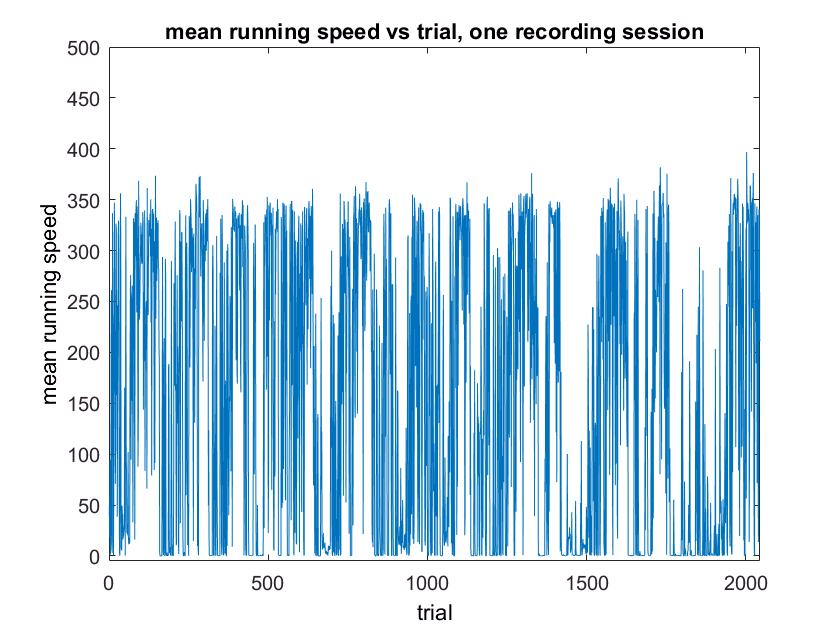


% line PLOT the running speed over trials/time for this session
figure
clear x_axis
x_axis = [1:length(meanSpeedAllTrials)]; % number of trials
% plot mean speed vs trials
plot(x_axis,meanSpeedAllTrials)
xlabel('trial')
ylabel('mean running speed')
title('mean running speed vs trial, one recording session')
xlim([0 length(meanSpeedAllTrials)])
ylim([-5 500])

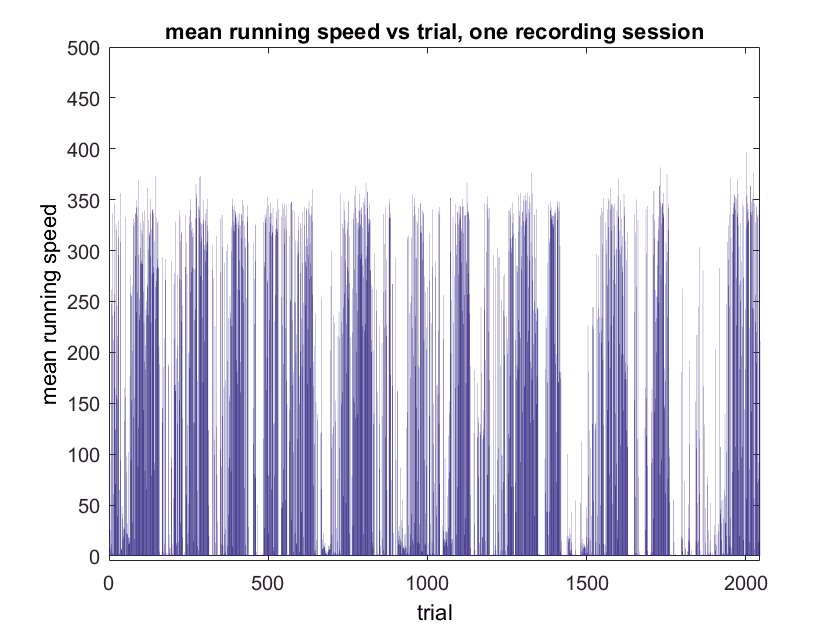


% BAR plot it
figure
bar(meanSpeedAllTrials)
xlabel('trial')
ylabel('mean running speed')
title('mean running speed vs trial, one recording session')
xlim([0 length(meanSpeedAllTrials)])
ylim([-5 500])


% HISTO showing FREQuency of different RUNning SPEEDs for FOR EVERY TRIAL

numTrials = length(meanSpeedAllTrials)

numTrials =         2044


numBins = 10

numBins =     10


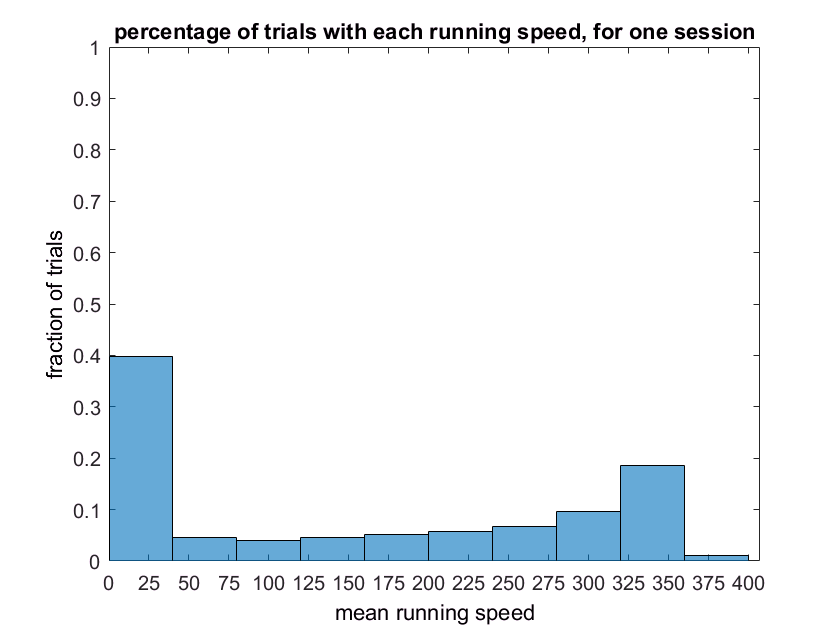


histogram(meanSpeedAllTrials,numBins,'normalization','probability')
ylabel('fraction of trials')
xlabel('mean running speed')
title('percentage of trials with each running speed, for one session')
xlim([0 round(max(meanSpeedAllTrials)+10)])
set(gca,'xtick',0:25:round(max(meanSpeedAllTrials)+10));
ylim([0 1])


% pick a threshold... what percentage of trials above & below it?
% pick 30 pix/frame threshold for running

numTrialsOverThresh = sum(meanSpeedAllTrials>=60)

numTrialsOverThresh =         1181


percentTrialsOverThresh = (numTrialsOverThresh/numTrials)*100

percentTrialsOverThresh =        57.779


% sumTrialsUnderThresh = sum(meanSpeedAllTrials<=60)
% percentTrialsUnderThresh = (numTrialsUnderThresh/numTrials)*100
% ratio_under2over_threshold = percentTrialsUnderThresh/percentTrialsOverThresh


% the meanSpeedAllTrials vector has 1 row, each column has
% the mean speed for that trial (*not* onset chunk)
% note that resolution for cursor is 6 times higher than for 
% imaging, so the extra frames (all trials-onset chunk) don't
% count for as much (divide by 6)


% indicies for trials that meet our threshold
idxRunTrials = find(meanSpeedAllTrials>=60);
length(idxRunTrials)

ans =         1181



% indicies for stationary trials
idxStatTrials = find(meanSpeedAllTrials<=60);
length(idxStatTrials)

ans =    863
